# Run Event-Related Spectral perturbation (ERSP) 

## Import data

Read BVA formatted data (.vhdr, .eeg and .vmrk)

clear all;close all 

% inputs
dirinput = 'W:\share_gfraga\SINEEG\Data\Pilot_October_2021';
diroutput = 'W:\share_gfraga\SINEEG\Analysis\Pilot_October_2021';

% Find files 
cd(dirinput)
measurement = 'Measurement 11' ;
filename = 'processed.vhdr';

 %% Import eeg 
 
[ALLEEG,EEG,CURRENTSET,ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\gfraga\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
Initializing SIFT...
Start SIFTing!
EEGLAB: adding "SIFT" v1.52 (see >> help eegplugin_sift)
EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)
You are using the latest version of EEGLAB.


set(gcf,'Visible','off')

EEG = pop_loadbv([dirinput, '\', measurement,'\'], filename,[], []);

pop_loadbv(): reading header file
Done.
pop_loadbv(): reading EEG data
The header file points to a binary file that does not exist
trying to open a binary file with the same name as the header
file and a different extension...
pop_loadbv(): scaling EEG data
pop_loadbv(): reading marker file
Done.
pop_loadbv() warning: data files in header and marker files inconsistent.


EEG.setname = ['eegset_',extractBefore(filename,'.vhdr')];

newsrate = 200;
for i=1:length(EEG.event)
        EEG.event(i).latency = EEG.event(i).latency / EEG.srate * newsrate;
end
EEG.srate = newsrate;
%load channel location 
EEG =pop_chanedit(EEG, 'load',{'W:\\share_gfraga\\SINEEG\\sample32chs.sph','filetype','sph'});

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


## Segment target-locked prestimulus


uniqueEvents = unique({EEG.event.type});
EEG = pop_epoch(EEG, uniqueEvents(16:20),[-0.900 0]);

pop_epoch():283 epochs selected
Epoching...

[ALLEEG,EEG,CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 1


EEG.setname = [extractBefore(filename,'.vhdr'),'_300pre'];

## Frequency analysis (Fieldtrip)

pop_saveset( EEG, 'filename','test2.set','filepath',diroutput);

Saving dataset...


% read in fieldtrip 
cfg = []; 
cfg.dataset = [diroutput,'\test2.set']; 

ft_data1 = ft_preprocessing(cfg)

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

ft_data1 = struct with fields:
           hdr: [1×1 struct]
         label: {32×1 cell}
          time: {[1×180 double]  [1×180 double]  [1×180 double]}
         trial: {[32×180 double]  [32×180 double]  [32×180 double]}
       fsample: 200
    sampleinfo: [3×2 double]
          elec: [1×1 struct]
           cfg: [1×1 struct]


## Phase lag index

Compute phase lag index matrix


% Compute phase lag index
metric = 'PLI';
n_channels = size(EEG.data,1);
n_datapoints = size(EEG.data,2);
n_segments = size(EEG.data,3);

EEG_MAT = zeros(n_channels, n_channels,n_segments);%CONnectivity matrix
for seg= 1:n_segments                
          segmentdata = EEG.data(:,:,seg);
          % Get phase 
          phase_signal = angle(hilbert(transpose(segmentdata )));
          
          % PLI between all channels
          PLI = zeros(n_channels, n_channels);
          for i=1:n_channels-1              
            for j=i+1:n_channels
                     PLI(i,j) = abs(mean(sign(phase_signal(:,i) - phase_signal(:,j))));
            end
          end
          PLI = triu(PLI);
          PLI = PLI + PLI';
          PLI(eye(size(PLI))~=0)=1;
          EEG_MAT(:,:,seg) = PLI;
end
 

### Plots per segment 

% Plots
close gcf;
list_segment = [string(1:n_segments),"mean"];
select_segment =  list_segment(3);

PLI matrix 

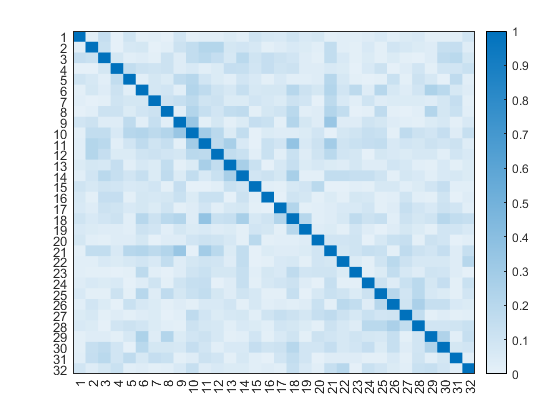

if select_segment=="mean" 
    matrix2plot = mean(EEG_MAT(:,:,:),3); % find selected segment in data 
else 
    matrix2plot = EEG_MAT(:,:,str2num(select_segment)); % find selected segment in data 
end


figure;
plot1 = heatmap(matrix2plot,'MissingDataColor',[0 0 0],'GridVisible','off','MissingDataLabel', " ");

Averages per channel

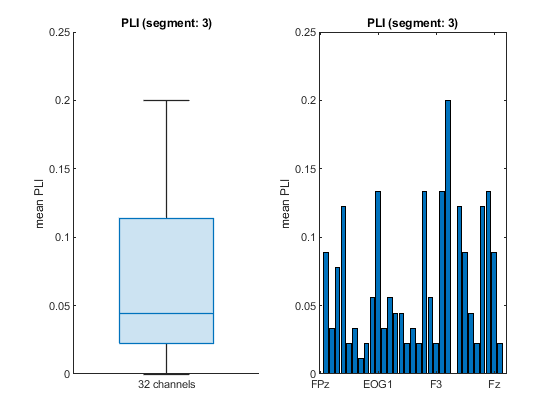


mean2plot = zeros(n_channels);
for chanidx = 1:n_channels
        mean2plot = [matrix2plot(chanidx,1:(chanidx-1)) matrix2plot(chanidx,(chanidx+1):end)];
end
      
      
subplot(1,2,1);
% Boxchart 
    h = boxchart(mean2plot,'JitterOutliers','on','DisplayName','mean PLI per channel');
    ylabel(['mean ' metric ]);
    xlabel('');
    xticklabels([num2str(n_channels), ' channels'])
    title([metric ' (segment: ', char(select_segment),')']);   
    
subplot(1,2,2)
% Barplot
h = bar(mean2plot,'DisplayName','meanCON2plot');
    ylabel(['mean ' metric]);
    %xlabel(['channels']);
    xticklabels(string({EEG.chanlocs.labels}))
    title([metric ' (segment: ', char(select_segment),')']);   


 clear mean2plot  

Means per segments 

list_chans2plot = ["all",deblank(string({EEG.chanlocs.labels}))];
select_channel =  list_chans2plot(10);

% Compute mean of all channels or select the values for a single channel 
if strcmp(select_channel,'all')== 1
        mean2plot = zeros(1,size(EEG_MAT,3));
        for i = 1:size(EEG_MAT,3)
            tmp=EEG_MAT(:,:,i);
            mean2plot(i) = mean(tmp(find(triu(ones(size(tmp))))));
        end

elseif  strcmp(select_channel,'all')== 0  

        chanidx = find(contains({EEG.chanlocs.labels}, select_channel))    
        mean2plot = zeros(1,size(EEG_MAT,3));
        for i = 1:size(EEG_MAT,3)
            mean2plot(i) =   mean([EEG_MAT(chanidx,1:(chanidx-1),i) EEG_MAT(chanidx,(chanidx+1):end,i)]);

        end
end

chanidx = 9

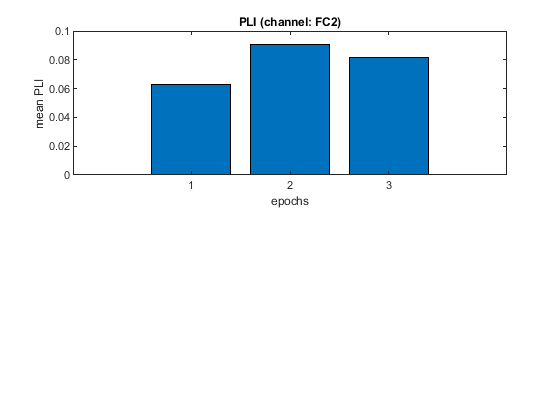

 
% Barplot    
figure; 
subplot(2,1,1);
   bar(mean2plot,'DisplayName','meanCON2plot');
    %xticklabels(list_segment);
    xlabel('epochs');
    ylabel(['mean ', metric]);
    title(['' metric ' (channel: ', char(select_channel),')']);   

xxxxxxxx

 

% 
% 
% 
% mean2plot = mean(mean(EEG_MAT(:,:,:),1),2);
% mean2plot = squeeze(mean2plot)';
% 
% % Barplot    
% figure; 
% subplot(2,1,2);
% h = bar(mean2plot,'DisplayName','meanCON2plot');
%     xticklabels(list_segment);
%     xlabel('epochs');
%     ylabel(['mean ', metric]);
%     title(['mean ' metric ' (channel: ', char(select_channel),')']);   

## Time frequency analysis    

% %[EEG ALLEEG CURRENTSET] = eeg_retrieve(ALLEEG,1);
% chans= deblank(string(char(EEG.chanlocs.labels)));
% select_chan =  chans(20);
% EEG = eeg_checkset( EEG );
% figure; pop_newtimef( EEG, 1, 1, [-300 0], [3         0.8] , 'topovec', 1, 'elocs', EEG.chanlocs, 'chaninfo', EEG.chaninfo, 'caption', char(select_chan), 'baseline',[0], 'plotphase', 'off', 'padratio', 1);
% figList = sort(get(0,'Children'));
% i = length(figList);
% figureSpec = {'Top-right click to open figure window, then double click the plots to zoom in and select data';};
% dim = [0.05, 0.05, 0.8, 0.0];
% a = annotation('textbox', dim, 'String', figureSpec, 'FitBoxToText', 'on', 'LineStyle', 'none');
% a.Color = 'red';
% a.FontSize = 7;
% a.HorizontalAlignment = 'left';
% 
% %annotation('textbox', dim,'shapeType','String', caption);
% %annotation('textbox', dim,'String', caption, 'FitBoxToText', 'on', 'LineStyle', 'none');
% 






% 
%  
% data = thingSpeakRead(12397,"NumDays",2,"Timeout",10,"OutputFormat","table");
% latestValues = height(data);
% 
% useSIUnits = false;
% 
% if useSIUnits == 0
%     disp("Current Conditions: Temperature " + data.TemperatureF(latestValues) + "F, Humidity " + data.Humidity(latestValues) + "%, Wind " + data.WindSpeedmph(latestValues) + "mph")
%     
%     plotWeatherData(data.Timestamps, data.TemperatureF, "F", data.WindSpeedmph, "mph", data.Humidity)
% 
% else
%     tempC = (5/9)*(data.TemperatureF-32);
%     tempC = round(tempC,2);
%     
%     windkmh = data.WindSpeedmph*1.60934;
%     disp("Current Conditions: Temperature " + tempC(latestValues) + "C, Humidity " + data.Humidity(latestValues) + "%, Wind " + windkmh(latestValues) + "kph")
%     
%     plotWeatherData(data.Timestamps, tempC, "C", windkmh, "kph", data.Humidity)
% end
% 

% function plotWeatherData(timestamps, tempData, tempUnits, windData, windUnits, humidityData)
%     subplot(3,1,1)
%     plot(timestamps, tempData)
%     xlabel("Date")
%     ylabel("Temp (" + tempUnits + ")")
%     title("Temperature (past 2 days)")
%     
%     subplot(3,1,2)
%     plot(timestamps, humidityData)
%     xlabel("Date")
%     ylabel("Humidity (%)")
%     title("Humidity (past 2 days)")
%     
%     subplot(3,1,3)
%     plot(timestamps, windData)
%     xlabel("Date")
%     ylabel("Wind Speed (" + windUnits + ")")
%     title("Wind (past 2 days)")
% end